% Mahri Kadyrova
% BE 3343
% Date: 05/10/2022
% Student ID: 1001869500
%Single Student Project
% Chapter questions

% Question 1 (chapter 6 question 2)

% Description: in each of the following problems, determine the best
% function y(x) (linear, exponential, or power function) to describe the
% data. Plot the function on the same plot with the data. Label and format
% the plots appropriately.

% a 

% Define x and y 
x1=[25 30 35 40 45]

x1 =     25    30    35    40    45


y1=[5 260 480 745 1100]

y1 =            5         260         480         745        1100


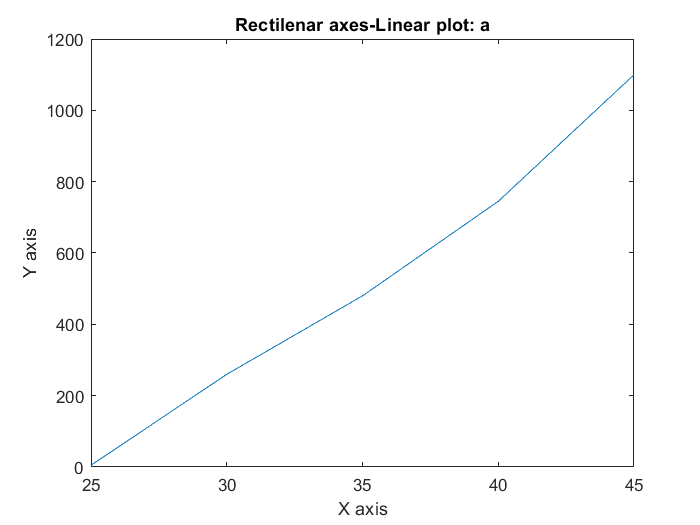


% Plot the x and y on rectilinear, loglog and semilogy axes

figure
plot(x1,y1)
title("Rectilenar axes-Linear plot: a")
xlabel("X axis")
ylabel("Y axis")

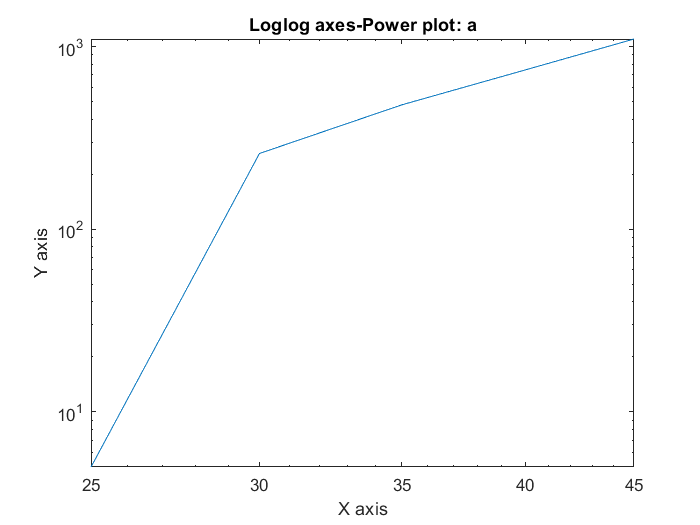



figure
loglog(x1,y1)
title("Loglog axes-Power plot: a")
xlabel("X axis")
ylabel("Y axis")

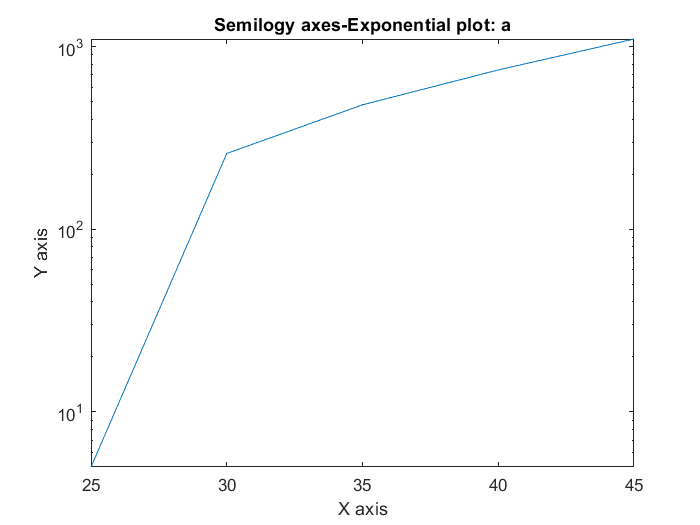


figure
semilogy(x1,y1)
title("Semilogy axes-Exponential plot: a")
xlabel("X axis")
ylabel("Y axis")


% Analyze the plots to see which plot gives a straight line or close to a
% straight line

a1=polyfit(x1,y1,1)

a1 = 	1.0e+03 *

    0.0535   -1.3545



% b 

% Define x and y 
x2=[2.5 3 3.5 4 4.5 5 5.5 6 7 8 9 10]

x2 =     2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    7.0000    8.0000    9.0000   10.0000


y2=[1500 1220 1050 915 810 745 690 620 520 480 410 390]

y2 =         1500        1220        1050         915         810         745         690         620         520         480         410         390


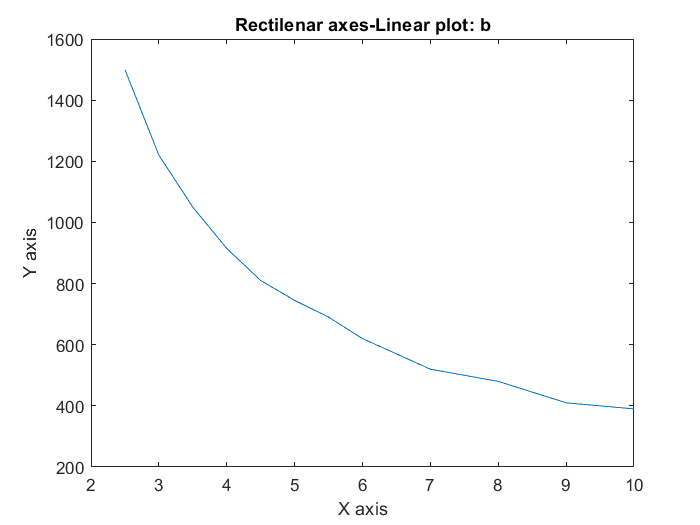


% Plot the x and y on rectilinear, loglog and semilogy axes

figure
plot(x2,y2)
title("Rectilenar axes-Linear plot: b")
xlabel("X axis")
ylabel("Y axis")

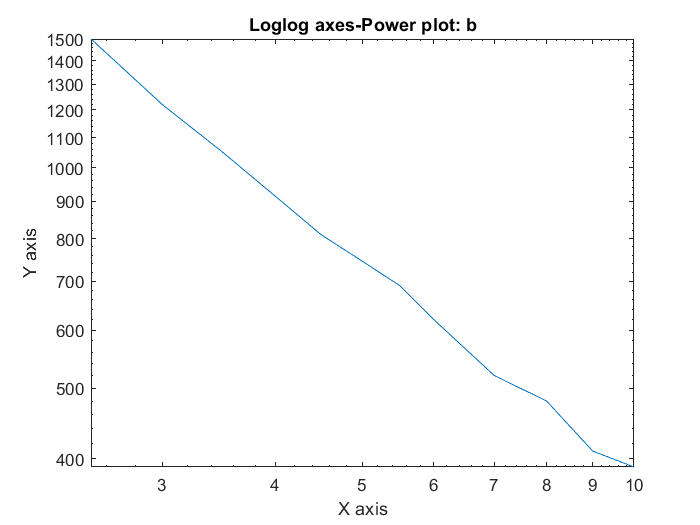



figure
loglog(x2,y2)
title("Loglog axes-Power plot: b")
xlabel("X axis")
ylabel("Y axis")

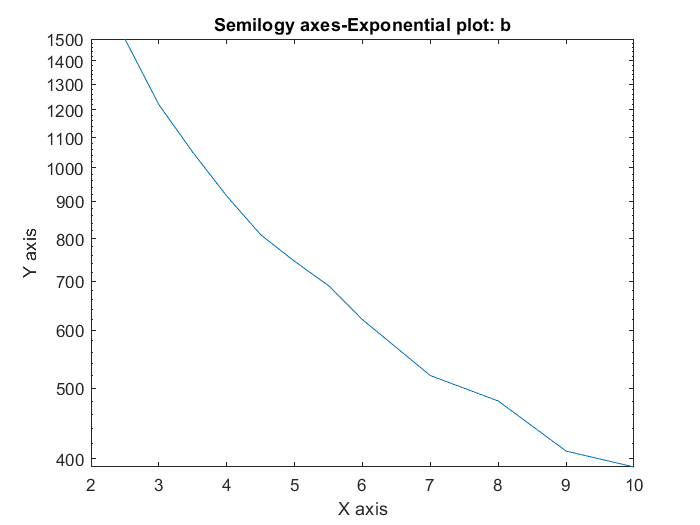


figure
semilogy(x2,y2)
title("Semilogy axes-Exponential plot: b")
xlabel("X axis")
ylabel("Y axis")


% Analyze the plots to see which plot gives a straight line or close to a
% straight line

% c

% Define x and y 
x3=[550 600 650 700 750]

x3 =    550   600   650   700   750


y3=[41.2 18.62 8.62 3.92 1.86]

y3 =    41.2000   18.6200    8.6200    3.9200    1.8600


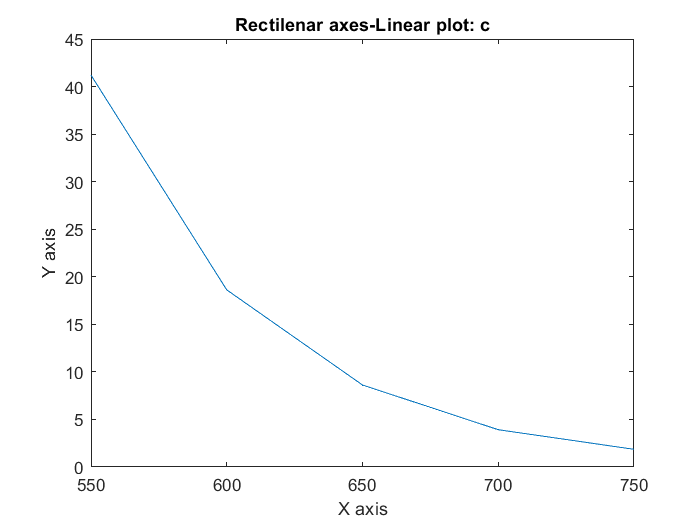


% Plot the x and y on rectilinear, loglog and semilogy axes

figure
plot(x3,y3)
title("Rectilenar axes-Linear plot: c")
xlabel("X axis")
ylabel("Y axis")

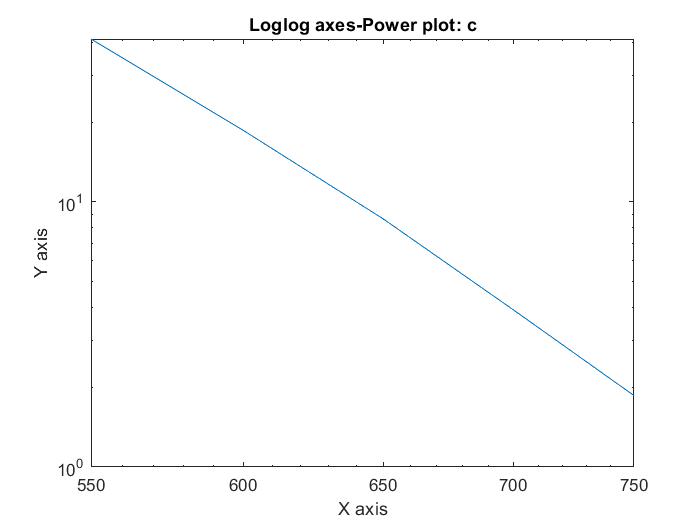



figure
loglog(x3,y3)
title("Loglog axes-Power plot: c")
xlabel("X axis")
ylabel("Y axis")

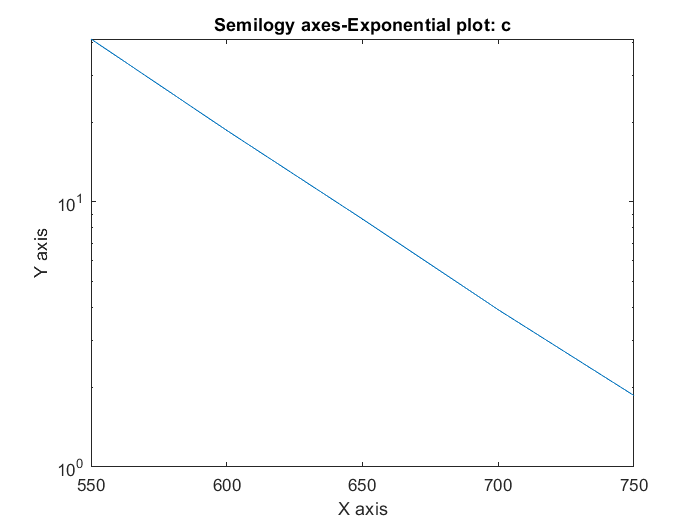


figure
semilogy(x3,y3)
title("Semilogy axes-Exponential plot: c")
xlabel("X axis")
ylabel("Y axis")


% Analyze the plots to see which plot gives a straight line or close to a
% straight line


a=['The data set a fits a rectilinear plot since it forms a straight line and the following linear function can be used y=',num2str(a1(1)),'*x',num2str(a1(2))]

a = 'The data set a fits linear plot and the equation is y=53.5*x-1354.5'

disp(a)

The data set a fits linear plot and the equation is y=53.5*x-1354.5


disp("The data set b fits loglog plot because it forms a straight line and the power function needs to be used")

The data set b fits power plot


disp("The data set c fits semilogy and loglog plots since it forms straight line on those plots and the exponential function needs to be used")

The data set c fits exponential plots


% Question 2 (chapter 6 question 9)
% Delete all previous information 
clear
clc
close all

% Description: the following data give the drying time T of a certain pint
% as a function of the amount of a certain additive A


%a: Find the first, second, third and fourth degree polynomials that fit
%the data and plot each polynomial with the data. Determine the quality of
%the curve t for each by computing J, S, and r^2

%Define x and y

A=[0 1 2 3 4 5 6 7 8 9] % oz

A =      0     1     2     3     4     5     6     7     8     9


T=[130 115 110 90 89 89 95 100 110 125] %min

T =    130   115   110    90    89    89    95   100   110   125


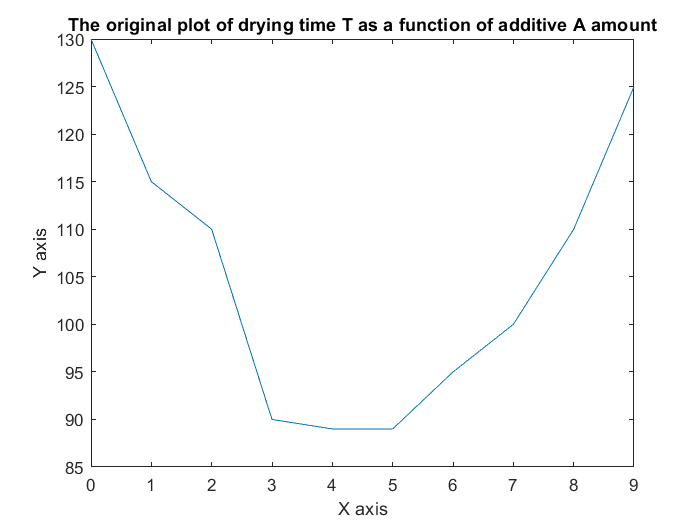


% Plot to observe the original plot of the data

plot(A,T)
title("The original plot of drying time T as a function of additive A amount")
xlabel("X axis")
ylabel("Y axis")


% first-degree polynomial
% use polyfit to obtain the first degree function coefficients
p1=polyfit(A,T,1)

p1 =    -0.6970  108.4364


% use polyval to obtain y values when inputting A data to p1 first degree
% polynomial function
x1=linspace(min(A),max(A),100)

x1 =          0    0.0909    0.1818    0.2727    0.3636    0.4545    0.5455    0.6364    0.7273    0.8182    0.9091    1.0000    1.0909    1.1818    1.2727    1.3636    1.4545    1.5455    1.6364    1.7273    1.8182    1.9091    2.0000    2.0909    2.1818    2.2727    2.3636    2.4545    2.5455    2.6364    2.7273    2.8182    2.9091    3.0000    3.0909    3.1818    3.2727    3.3636    3.4545    3.5455    3.6364    3.7273    3.8182    3.9091    4.0000    4.0909    4.1818    4.2727    4.3636    4.4545


y1=polyval(p1,x1)

y1 =   108.4364  108.3730  108.3096  108.2463  108.1829  108.1196  108.0562  107.9928  107.9295  107.8661  107.8028  107.7394  107.6760  107.6127  107.5493  107.4860  107.4226  107.3592  107.2959  107.2325  107.1691  107.1058  107.0424  106.9791  106.9157  106.8523  106.7890  106.7256  106.6623  106.5989  106.5355  106.4722  106.4088  106.3455  106.2821  106.2187  106.1554  106.0920  106.0287  105.9653  105.9019  105.8386  105.7752  105.7118  105.6485  105.5851  105.5218  105.4584  105.3950  105.3317


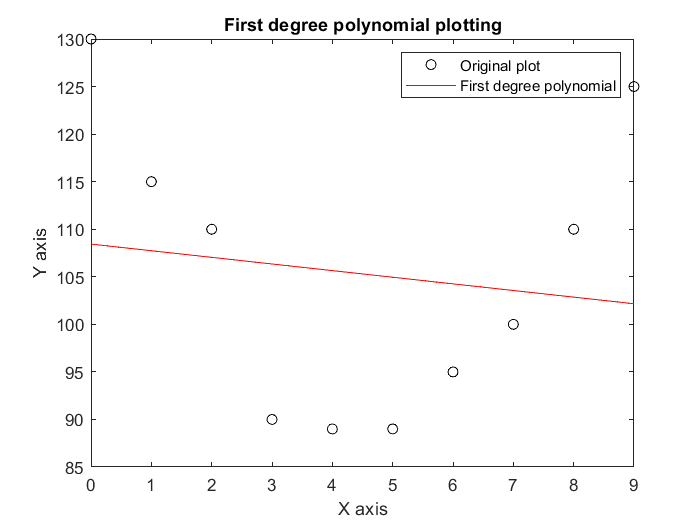


%plot the original and the first degree polynomial data to analyze the
%plots
figure
plot(A,T,'ko')
hold on
plot(x1,y1,'r')
title("First degree polynomial plotting")
xlabel("X axis")
ylabel("Y axis")
legend("Original plot","First degree polynomial")


% calculate J, S, and r^2 using below formulas
 
for k=1:4;
    coeff1=polyfit(A,T,1);
    J1(k)=sum((polyval(coeff1,A)-T).^2);
    end

mu1=mean(T);
for k=1:4;
    S1(k)=sum((T-mu1).^2);
    r2_1(k)=1-J1(k)/S1(k);    
end
disp("The J value for the first degree polynomial fitting is:")

The J value for the first degree polynomial fitting is:


disp(J1)

   1.0e+03 *

    1.9960    1.9960    1.9960    1.9960



disp("The S value for the first degree polynomial fitting is:")

The S value for the first degree polynomial fitting is:


disp(S1)

   1.0e+03 *

    2.0361    2.0361    2.0361    2.0361



disp("The r^2 value for the first degree polynomial fitting is:")

The r^2 value for the first degree polynomial fitting is:


disp(r2_1)

    0.0197    0.0197    0.0197    0.0197




% second-degree polynomial
% use polyfit to obtain the second degree function coefficients
p2=polyfit(A,T,2)

p2 =     1.9053  -17.8447  131.3000


% use polyval to obtain y values when inputting A data to p2 second degree
% polynomial function
x2=linspace(min(A),max(A),100)

x2 =          0    0.0909    0.1818    0.2727    0.3636    0.4545    0.5455    0.6364    0.7273    0.8182    0.9091    1.0000    1.0909    1.1818    1.2727    1.3636    1.4545    1.5455    1.6364    1.7273    1.8182    1.9091    2.0000    2.0909    2.1818    2.2727    2.3636    2.4545    2.5455    2.6364    2.7273    2.8182    2.9091    3.0000    3.0909    3.1818    3.2727    3.3636    3.4545    3.5455    3.6364    3.7273    3.8182    3.9091    4.0000    4.0909    4.1818    4.2727    4.3636    4.4545


y2=polyval(p2,x2)

y2 =   131.3000  129.6935  128.1185  126.5750  125.0630  123.5824  122.1334  120.7159  119.3298  117.9752  116.6522  115.3606  114.1005  112.8719  111.6748  110.5092  109.3751  108.2725  107.2014  106.1618  105.1536  104.1770  103.2318  102.3182  101.4360  100.5853   99.7661   98.9784   98.2222   97.4975   96.8043   96.1426   95.5124   94.9136   94.3464   93.8106   93.3064   92.8336   92.3923   91.9826   91.6043   91.2575   90.9422   90.6584   90.4061   90.1852   89.9959   89.8381   89.7117   89.6169


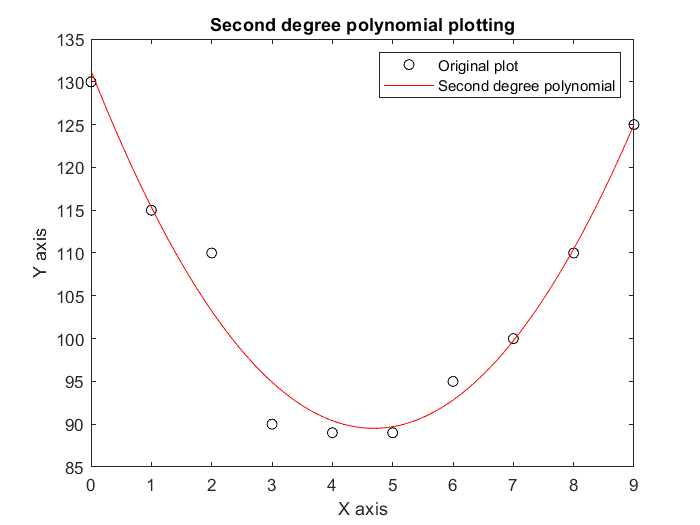


%plot the original and the second degree polynomial data to analyze the
%plots
figure
plot(A,T,'ko')
hold on
plot(x2,y2,'r')
title("Second degree polynomial plotting")
xlabel("X axis")
ylabel("Y axis")
legend("Original plot","Second degree polynomial")


% calculate J, S, and r^2 using below formulas
 
for k=1:4;
    coeff2=polyfit(A,T,2);
    J2(k)=sum((polyval(coeff2,A)-T).^2);
    end

mu2=mean(T);
for k=1:4;
    S2(k)=sum((T-mu2).^2);
    r2_2(k)=1-J2(k)/S2(k);    
end
disp("The J value for the second degree polynomial fitting is:")

The J value for the second degree polynomial fitting is:


disp(J2)

   79.2894   79.2894   79.2894   79.2894



disp("The S value for the second degree polynomial fitting is:")

The S value for the second degree polynomial fitting is:


disp(S2)

   1.0e+03 *

    2.0361    2.0361    2.0361    2.0361



disp("The r^2 value for the second degree polynomial fitting is:")

The r^2 value for the second degree polynomial fitting is:


disp(r2_2)

    0.9611    0.9611    0.9611    0.9611




% third-degree polynomial
% use polyfit to obtain the third degree function coefficients
p3=polyfit(A,T,3)

p3 =     0.0107    1.7611  -17.3522  131.0308


% use polyval to obtain y values when inputting A data to p3 third degree
% polynomial function
x3=linspace(min(A),max(A),100)

x3 =          0    0.0909    0.1818    0.2727    0.3636    0.4545    0.5455    0.6364    0.7273    0.8182    0.9091    1.0000    1.0909    1.1818    1.2727    1.3636    1.4545    1.5455    1.6364    1.7273    1.8182    1.9091    2.0000    2.0909    2.1818    2.2727    2.3636    2.4545    2.5455    2.6364    2.7273    2.8182    2.9091    3.0000    3.0909    3.1818    3.2727    3.3636    3.4545    3.5455    3.6364    3.7273    3.8182    3.9091    4.0000    4.0909    4.1818    4.2727    4.3636    4.4545


y3=polyval(p3,x3)

y3 =   131.0308  129.4679  127.9341  126.4296  124.9543  123.5083  122.0916  120.7044  119.3466  118.0183  116.7195  115.4503  114.2108  113.0010  111.8209  110.6705  109.5500  108.4594  107.3987  106.3680  105.3673  104.3967  103.4562  102.5458  101.6657  100.8159   99.9963   99.2072   98.4484   97.7201   97.0223   96.3550   95.7184   95.1124   94.5370   93.9925   93.4787   92.9958   92.5438   92.1227   91.7326   91.3735   91.0455   90.7487   90.4830   90.2485   90.0454   89.8735   89.7330   89.6240


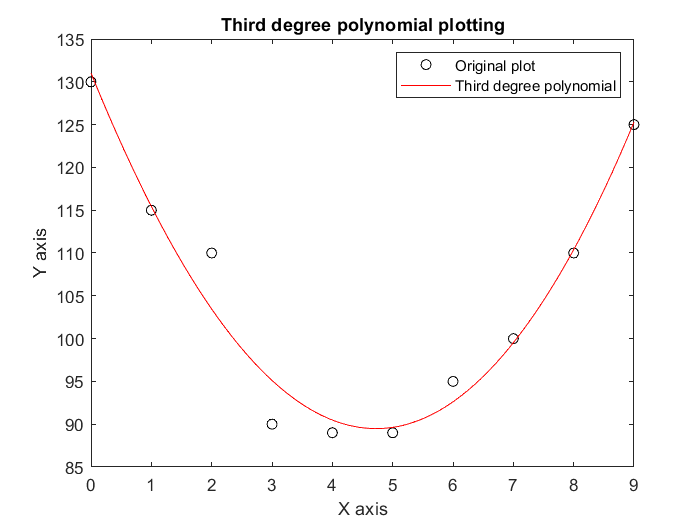


%plot the original and the third degree polynomial data to analyze the
%plots
figure
plot(A,T,'ko')
hold on
plot(x3,y3,'r')
title("Third degree polynomial plotting")
xlabel("X axis")
ylabel("Y axis")
legend("Original plot","Third degree polynomial")


% calculate J, S, and r^2 using below formulas
 
for k=1:4;
    coeff3=polyfit(A,T,3);
    J3(k)=sum((polyval(coeff3,A)-T).^2);
    end

mu3=mean(T);
for k=1:4;
    S3(k)=sum((T-mu3).^2);
    r2_3(k)=1-J3(k)/S3(k);    
end
disp("The J value for the third degree polynomial fitting is:")

The J value for the third degree polynomial fitting is:


disp(J3)

   78.9368   78.9368   78.9368   78.9368



disp("The S value for the third degree polynomial fitting is:")

The S value for the third degree polynomial fitting is:


disp(S3)

   1.0e+03 *

    2.0361    2.0361    2.0361    2.0361



disp("The r^2 value for the third degree polynomial fitting is:")

The r^2 value for the third degree polynomial fitting is:


disp(r2_3)

    0.9612    0.9612    0.9612    0.9612




% fourth-degree polynomial
% use polyfit to obtain the fourth degree function coefficients
p4=polyfit(A,T,4)

p4 =    -0.0249    0.4591   -0.7551  -12.8679  129.9545


% use polyval to obtain y values when inputting A data to p4 fourth degree
% polynomial function
x4=linspace(min(A),max(A),100)

x4 =          0    0.0909    0.1818    0.2727    0.3636    0.4545    0.5455    0.6364    0.7273    0.8182    0.9091    1.0000    1.0909    1.1818    1.2727    1.3636    1.4545    1.5455    1.6364    1.7273    1.8182    1.9091    2.0000    2.0909    2.1818    2.2727    2.3636    2.4545    2.5455    2.6364    2.7273    2.8182    2.9091    3.0000    3.0909    3.1818    3.2727    3.3636    3.4545    3.5455    3.6364    3.7273    3.8182    3.9091    4.0000    4.0909    4.1818    4.2727    4.3636    4.4545


y4=polyval(p4,x4)

y4 =   129.9545  128.7788  127.5927  126.3981  125.1971  123.9915  122.7833  121.5743  120.3663  119.1611  117.9603  116.7657  115.5790  114.4016  113.2352  112.0813  110.9414  109.8168  108.7091  107.6195  106.5494  105.5000  104.4726  103.4684  102.4884  101.5339  100.6059   99.7055   98.8335   97.9910   97.1788   96.3979   95.6490   94.9330   94.2505   93.6023   92.9891   92.4114   91.8699   91.3650   90.8973   90.4672   90.0752   89.7216   89.4068   89.1310   88.8945   88.6975   88.5402   88.4227


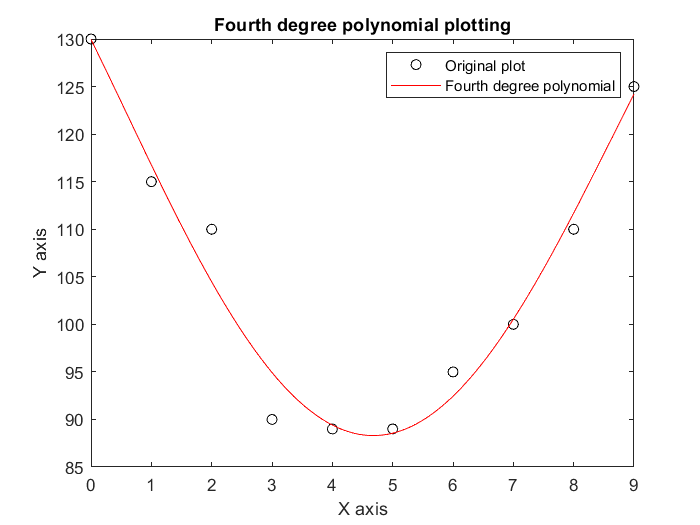


%plot the original and the fourth degree polynomial data to analyze the
%plots
figure
plot(A,T,'ko')
hold on
plot(x4,y4,'r')
title("Fourth degree polynomial plotting")
xlabel("X axis")
ylabel("Y axis")
legend("Original plot","Fourth degree polynomial")


% calculate J, S, and r^2 using below formulas
 
for k=1:4;
    coeff4=polyfit(A,T,4);
    J4(k)=sum((polyval(coeff4,A)-T).^2);
    end

mu4=mean(T);
for k=1:4;
    S4(k)=sum((T-mu4).^2);
    r2_4(k)=1-J4(k)/S4(k);    
end
disp("The J value for the fourth degree polynomial fitting is:")

The J value for the fourth degree polynomial fitting is:


disp(J4)

   68.7127   68.7127   68.7127   68.7127



disp("The S value for the fourth degree polynomial fitting is:")

The S value for the fourth degree polynomial fitting is:


disp(S4)

   1.0e+03 *

    2.0361    2.0361    2.0361    2.0361



disp("The r^2 value for the fourth degree polynomial fitting is:")

The r^2 value for the fourth degree polynomial fitting is:


disp(r2_4)

    0.9663    0.9663    0.9663    0.9663




disp("After analyzing the r^2 values of first, second, third, and fourth degree polynomials, the r^2 value of fourth polynomial is the closest to 1 thus is the optimal function")

After analyzing the r^2 values of first, second, third, and fourth degree polynomials, the r^2 value of fourth polynomial is the closest to 1 thus is the optimal function



%b: use the polynomial giving the best fit to estimate the amount of
%additive that minimizes the drying time

%plot the original and the fourth degree polynomial data to analyze the
%plots
figure
plot(A,T,'ko')
hold on
plot(x4,y4,'r')
title("Fourth degree polynomial plotting")
xlabel("X axis")
ylabel("Y axis")
legend("Original plot","Fourth degree polynomial")

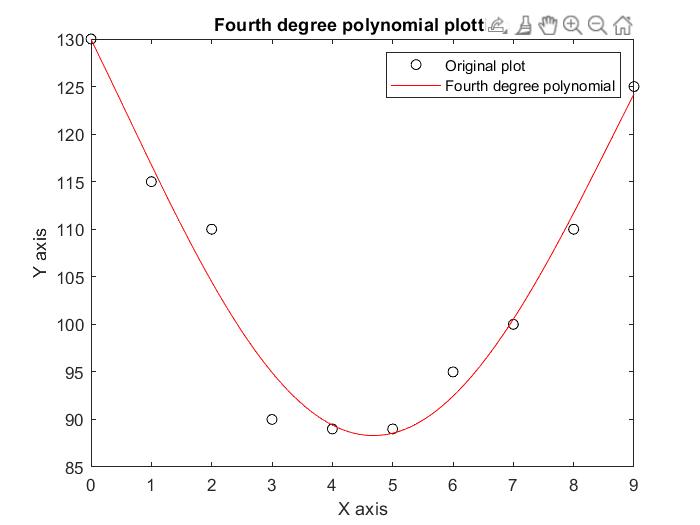

minA = 4.6492

minT = 88.3119


%obtain the minimum additive A to minimize time T 

[minA minT]=ginput(1)

% Question 3 (chapter 6 question 12)

% Delete all previous information 
clear
clc
close all

% Description:The following representss pressure samplesm in pounds per
% square inch (psi), taken in a fuel line once every second for 10 sec.

% a : fit a first, second, third degree polynomial to these data, Plot the
% curve fits along with the data points.

% define x and y which are t and p, respectively
t=[1 2 3 4 5 6 7 8 9 10]

t =      1     2     3     4     5     6     7     8     9    10


p=[26.1 27.0 28.2 29.0 29.8 30.6 31.1 31.3 31.0 30.5]

p =    26.1000   27.0000   28.2000   29.0000   29.8000   30.6000   31.1000   31.3000   31.0000   30.5000




% first-degree polynomial
% use polyfit to obtain the first degree function coefficients
p1=polyfit(t,p,1)

p1 =     0.5467   26.4533


% use polyval to obtain y values when inputting A data to p1 first degree
% polynomial function
x1=linspace(min(t),max(t),100)

x1 =     1.0000    1.0909    1.1818    1.2727    1.3636    1.4545    1.5455    1.6364    1.7273    1.8182    1.9091    2.0000    2.0909    2.1818    2.2727    2.3636    2.4545    2.5455    2.6364    2.7273    2.8182    2.9091    3.0000    3.0909    3.1818    3.2727    3.3636    3.4545    3.5455    3.6364    3.7273    3.8182    3.9091    4.0000    4.0909    4.1818    4.2727    4.3636    4.4545    4.5455    4.6364    4.7273    4.8182    4.9091    5.0000    5.0909    5.1818    5.2727    5.3636    5.4545


y1=polyval(p1,x1)

y1 =    27.0000   27.0497   27.0994   27.1491   27.1988   27.2485   27.2982   27.3479   27.3976   27.4473   27.4970   27.5467   27.5964   27.6461   27.6958   27.7455   27.7952   27.8448   27.8945   27.9442   27.9939   28.0436   28.0933   28.1430   28.1927   28.2424   28.2921   28.3418   28.3915   28.4412   28.4909   28.5406   28.5903   28.6400   28.6897   28.7394   28.7891   28.8388   28.8885   28.9382   28.9879   29.0376   29.0873   29.1370   29.1867   29.2364   29.2861   29.3358   29.3855   29.4352


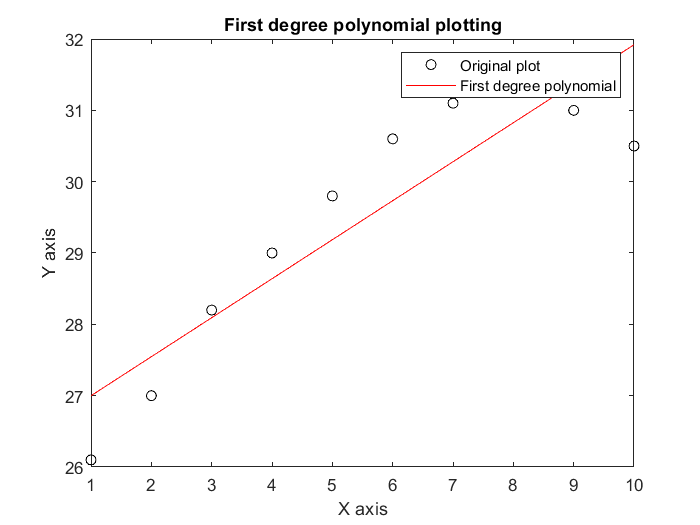


%plot the original and the first degree polynomial data to analyze the
%plots
figure
plot(t,p,'ko')
hold on
plot(x1,y1,'r')
title("First degree polynomial plotting")
xlabel("X axis")
ylabel("Y axis")
legend("Original plot","First degree polynomial")


% calculate J, S, and r^2 using below formulas
 
for k=1:4;
    coeff1=polyfit(t,p,1);
    J1(k)=sum((polyval(coeff1,t)-p).^2);
    end

mu1=mean(p);
for k=1:4;
    S1(k)=sum((p-mu1).^2);
    r2_1(k)=1-J1(k)/S1(k);    
end
disp("The J value for the first degree polynomial fitting is:")

The J value for the first degree polynomial fitting is:


disp(J1)

    5.4293    5.4293    5.4293    5.4293



disp("The S value for the first degree polynomial fitting is:")

The S value for the first degree polynomial fitting is:


disp(S1)

   30.0840   30.0840   30.0840   30.0840



disp("The r^2 value for the first degree polynomial fitting is:")

The r^2 value for the first degree polynomial fitting is:


disp(r2_1)

    0.8195    0.8195    0.8195    0.8195





% second-degree polynomial
% use polyfit to obtain the second degree function coefficients
p2=polyfit(t,p,2)

p2 =    -0.0977    1.6217   24.3033


% use polyval to obtain y values when inputting A data to p2 second degree
% polynomial function
x2=linspace(min(t),max(t),100)

x2 =     1.0000    1.0909    1.1818    1.2727    1.3636    1.4545    1.5455    1.6364    1.7273    1.8182    1.9091    2.0000    2.0909    2.1818    2.2727    2.3636    2.4545    2.5455    2.6364    2.7273    2.8182    2.9091    3.0000    3.0909    3.1818    3.2727    3.3636    3.4545    3.5455    3.6364    3.7273    3.8182    3.9091    4.0000    4.0909    4.1818    4.2727    4.3636    4.4545    4.5455    4.6364    4.7273    4.8182    4.9091    5.0000    5.0909    5.1818    5.2727    5.3636    5.4545


y2=polyval(p2,x2)

y2 =    25.8273   25.9561   26.0834   26.2090   26.3330   26.4554   26.5761   26.6953   26.8128   26.9288   27.0431   27.1558   27.2668   27.3763   27.4841   27.5904   27.6950   27.7980   27.8994   27.9992   28.0973   28.1939   28.2888   28.3821   28.4738   28.5639   28.6523   28.7392   28.8244   28.9080   28.9900   29.0704   29.1492   29.2264   29.3019   29.3758   29.4481   29.5188   29.5879   29.6554   29.7212   29.7855   29.8481   29.9091   29.9685   30.0263   30.0824   30.1370   30.1899   30.2412


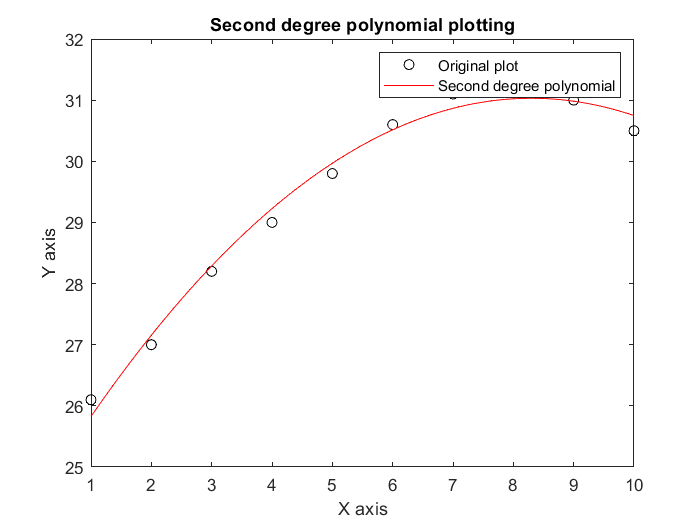


%plot the original and the second degree polynomial data to analyze the
%plots
figure
plot(t,p,'ko')
hold on
plot(x2,y2,'r')
title("Second degree polynomial plotting")
xlabel("X axis")
ylabel("Y axis")
legend("Original plot","Second degree polynomial")


% calculate J, S, and r^2 using below formulas
 
for k=1:4;
    coeff2=polyfit(t,p,2);
    J2(k)=sum((polyval(coeff2,t)-p).^2);
    end

mu2=mean(p);
for k=1:4;
    S2(k)=sum((p-mu2).^2);
    r2_2(k)=1-J2(k)/S2(k);    
end
disp("The J value for the second degree polynomial fitting is:")

The J value for the second degree polynomial fitting is:


disp(J2)

    0.3866    0.3866    0.3866    0.3866



disp("The S value for the second degree polynomial fitting is:")

The S value for the second degree polynomial fitting is:


disp(S2)

   30.0840   30.0840   30.0840   30.0840



disp("The r^2 value for the second degree polynomial fitting is:")

The r^2 value for the second degree polynomial fitting is:


disp(r2_2)

    0.9871    0.9871    0.9871    0.9871






% third-degree polynomial
% use polyfit to obtain the third degree function coefficients
p3=polyfit(t,p,3)

p3 =    -0.0106    0.0766    0.8175   25.2100


% use polyval to obtain y values when inputting A data to p3 third degree
% polynomial function
x3=linspace(min(t),max(t),100)

x3 =     1.0000    1.0909    1.1818    1.2727    1.3636    1.4545    1.5455    1.6364    1.7273    1.8182    1.9091    2.0000    2.0909    2.1818    2.2727    2.3636    2.4545    2.5455    2.6364    2.7273    2.8182    2.9091    3.0000    3.0909    3.1818    3.2727    3.3636    3.4545    3.5455    3.6364    3.7273    3.8182    3.9091    4.0000    4.0909    4.1818    4.2727    4.3636    4.4545    4.5455    4.6364    4.7273    4.8182    4.9091    5.0000    5.0909    5.1818    5.2727    5.3636    5.4545


y3=polyval(p3,x3)

y3 =    26.0936   26.1793   26.2657   26.3528   26.4405   26.5287   26.6174   26.7066   26.7962   26.8862   26.9765   27.0670   27.1578   27.2487   27.3397   27.4309   27.5220   27.6132   27.7042   27.7952   27.8860   27.9766   28.0669   28.1569   28.2466   28.3358   28.4246   28.5130   28.6007   28.6879   28.7745   28.8603   28.9455   29.0298   29.1133   29.1960   29.2777   29.3584   29.4381   29.5168   29.5943   29.6707   29.7459   29.8198   29.8924   29.9637   30.0335   30.1019   30.1688   30.2342


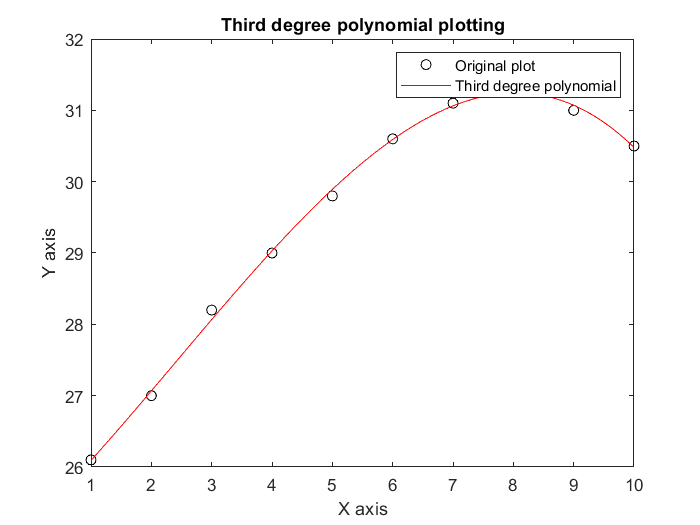


%plot the original and the first degree polynomial data to analyze the
%plots
figure
plot(t,p,'ko')
hold on
plot(x3,y3,'r')
title("Third degree polynomial plotting")
xlabel("X axis")
ylabel("Y axis")
legend("Original plot","Third degree polynomial")


% calculate J, S, and r^2 using below formulas
 
for k=1:4;
    coeff3=polyfit(t,p,3);
    J3(k)=sum((polyval(coeff3,t)-p).^2);
    end

mu3=mean(p);
for k=1:4;
    S3(k)=sum((p-mu3).^2);
    r2_3(k)=1-J3(k)/S3(k);    
end
disp("The J value for the third degree polynomial fitting is:")

The J value for the third degree polynomial fitting is:


disp(J3)

    0.0417    0.0417    0.0417    0.0417



disp("The S value for the third degree polynomial fitting is:")

The S value for the third degree polynomial fitting is:


disp(S3)

   30.0840   30.0840   30.0840   30.0840



disp("The r^2 value for the third degree polynomial fitting is:")

The r^2 value for the third degree polynomial fitting is:


disp(r2_3)

    0.9986    0.9986    0.9986    0.9986





% b: use the results from part a to predict the pressure at t=11 sec.
% Explain which curve fit gives the most reliable prediction. Consider the
% coefficients of determination and the residuals for each fit in making
% your decision.

disp("The coefficient of determination of the first, second, and third degree polynomial are:")

The coefficient of determination of the first, second, and third degree polynomial are:


disp(r2_1)

    0.8195    0.8195    0.8195    0.8195



disp(r2_2)

    0.9871    0.9871    0.9871    0.9871



disp(r2_3)

    0.9986    0.9986    0.9986    0.9986




disp("As can be observed from the above coefficients of determination, third degree polynomials seems to be closest to 1 which is the optimal function")

% To find t=11, use polyval function with p3 third degree polynimal fitted
% function

t_11=polyval(p3,11)

disp("The pressure when t=11 sec is :")
disp(t_11)

% Question 4 (chapter 6 question 14)

% Description: the solubility of salt in water is a funciton of the water
% temperature. Let S represent the solubility of NaCL as grams of salt in
% 100 g of water. Let T be temperature in C. Use the following data to
% obtain a curve for S as a function of T. Usee the fit to estimate S when
% T=25 C

% delete all previous information and entries
clear
clc
close all

% Define x and y which are T and S, respectively
x=[10 20 30 40 50 60 70 80 90]

x =     10    20    30    40    50    60    70    80    90


y=[35 35.6 36.25 36.9 37.5 38.1 38.8 39.4 40]

y =    35.0000   35.6000   36.2500   36.9000   37.5000   38.1000   38.8000   39.4000   40.0000



% the following code will be used to figure out which degree polynomial
% fits the data best

% polyfit is used to find coefficients of first, second, third, fourth, and
% fifth degree polynomials that fits the original data 
p1=polyfit(x,y,1)

p1 =     0.0628   34.3639


p2=polyfit(x,y,2)

p2 =    -0.0000    0.0633   34.3560


p3=polyfit(x,y,3)

p3 =    -0.0000    0.0001    0.0603   34.3865


p4=polyfit(x,y,4)

p4 =    -0.0000    0.0000   -0.0001    0.0657   34.3472


p5=polyfit(x,y,5)

p5 =    -0.0000    0.0000   -0.0001    0.0023    0.0231   34.5917


x1=linspace(min(x),max(x),100)

x1 =    10.0000   10.8081   11.6162   12.4242   13.2323   14.0404   14.8485   15.6566   16.4646   17.2727   18.0808   18.8889   19.6970   20.5051   21.3131   22.1212   22.9293   23.7374   24.5455   25.3535   26.1616   26.9697   27.7778   28.5859   29.3939   30.2020   31.0101   31.8182   32.6263   33.4343   34.2424   35.0505   35.8586   36.6667   37.4747   38.2828   39.0909   39.8990   40.7071   41.5152   42.3232   43.1313   43.9394   44.7475   45.5556   46.3636   47.1717   47.9798   48.7879   49.5960


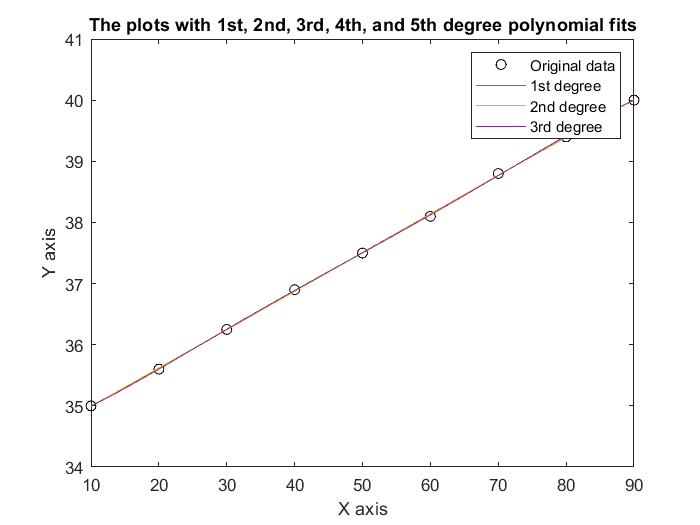


% polyval will be used to plot x values on those specific functions

figure
plot(x,y,'ko')
% hold on
% plot(x1,polyval(p1,x1))
% hold on
% plot(x1,polyval(p2,x1))
hold on
plot(x1,polyval(p3,x1))
hold on
plot(x1,polyval(p4,x1))
hold on
plot(x1,polyval(p5,x1))
title("The plots with 1st, 2nd, 3rd, 4th, and 5th degree polynomial fits")
xlabel("X axis")
ylabel("Y axis")
legend("Original data","1st degree","2nd degree","3rd degree","4th degree","5th degree")


% Obtain an equation describing the polynomial fit
p1=polyfit(x,y,1)

p1 =     0.0628   34.3639


m=p1(1)

m = 0.0628

b=p1(2)

b = 34.3639


ans=['After observing the plot of 5 polynomial fits, it is obvious that the data fits the first degree polynomial and will have linear function which can be described as follows: S=',num2str(m),'*T+',num2str(b)]

ans = 'After observing the plot of 5 polynomial fits, it is obvious that the data fits the first degree polynomial and will have linear function which can be described as follows: y=0.062833*x+34.3639'

disp(ans)

After observing the plot of 5 polynomial fits, it is obvious that the data fits the first degree polynomial and will have linear function which can be described as follows: y=0.062833*x+34.3639



% find S when T=25 which is finding y when x=25
S=polyval(p1,25)

ansb=['The solubility of NaCl described by S when T is 25 C is ',num2str(S)]
disp(ansb)

% Question 5 (chapter 6 question 16)

% Description: The following function is linear in the parameters a1 and
% a2: y(x)=a1+a2*ln(x). Use the least squares regression with the following
% data to estimate the values of a1 and a2. Use the curve fit to estimate
% the values of y at x=2.5 and at x=11.

% delete all the previous data and entries
clear
clc
close all

% define x and y

x=[1 2 3 4 5 6 7 8 9 10]

x =      1     2     3     4     5     6     7     8     9    10


y=[10 14 16 18 19 20 21 22 23 23]

y =     10    14    16    18    19    20    21    22    23    23




% Least squares method from textbook. Important to remember that x=ln(x)

% create symbolic variables a and b
% a is a1 and b is a2
syms a b 
% find the J function and its sum
J=(a+b*log(x)-y).^2

$$J = \left(\begin{array}{cccccccccc} {\left(a-10\right)}^{2} & {\left(a+\frac{6243314768165359\,b}{9007199254740992}-14\right)}^{2} & {\left(a+\frac{2473854946935173\,b}{2251799813685248}-16\right)}^{2} & {\left(a+\frac{6243314768165359\,b}{4503599627370496}-18\right)}^{2} & {\left(a+\frac{7248263982714163\,b}{4503599627370496}-19\right)}^{2} & {\left(a+\frac{4034683638976513\,b}{2251799813685248}-20\right)}^{2} & {\left(a+\frac{8763600222181975\,b}{4503599627370496}-21\right)}^{2} & {\left(a+\frac{4682486076124019\,b}{2251799813685248}-22\right)}^{2} & {\left(a+\frac{4947709893870347\,b}{2251799813685248}-23\right)}^{2} & {\left(a+\frac{2592480341699211\,b}{1125899906842624}-23\right)}^{2} \end{array}\right)$$

J=sum(J)

$$J = {\left(a+\frac{2473854946935173\,b}{2251799813685248}-16\right)}^{2}+{\left(a-10\right)}^{2}+{\left(a+\frac{4682486076124019\,b}{2251799813685248}-22\right)}^{2}+{\left(a+\frac{4947709893870347\,b}{2251799813685248}-23\right)}^{2}+{\left(a+\frac{8763600222181975\,b}{4503599627370496}-21\right)}^{2}+{\left(a+\frac{2592480341699211\,b}{1125899906842624}-23\right)}^{2}+{\left(a+\frac{7248263982714163\,b}{4503599627370496}-19\right)}^{2}+{\left(a+\frac{4034683638976513\,b}{2251799813685248}-20\right)}^{2}+{\left(a+\frac{6243314768165359\,b}{9007199254740992}-14\right)}^{2}+{\left(a+\frac{6243314768165359\,b}{4503599627370496}-18\right)}^{2}$$


% find derivatives with respect to a1 and a2
a1=diff(J,a)

$$a1 = 20\,a+\frac{136048453671506249\,b}{4503599627370496}-372$$

a2=diff(J,b)

$$a2 = \frac{136048453671506249\,a}{4503599627370496}+\frac{2243254282149086097508830330870413\,b}{40564819207303340847894502572032}-\frac{1390518427306330813}{2251799813685248}$$


% set the integer value to 4 for each value
a1=vpa(a1,4)

$$a1 = 20.0\,a+30.21\,b-372.0$$

a2=vpa(a2,4)

$$a2 = 30.21\,a+55.3\,b-617.5$$


% solve the equations for a and b by setting them equal to 0 
eqns=[a1==0, a2==0];
S=solve(eqns,[a b])

S = struct with fields:
    a: [1×1 sym]
    b: [1×1 sym]



% obtain a and b values which are a and b respectively
a=vpa(S.a,4)

$$a = 9.912$$

b=vpa(S.b,4)

$$b = 5.752$$


disp("The a1 was calculated to be: ")

The a1 was calculated to be: 


disp(a)

$$9.912$$


disp("The a2 was calculated to be: ")

The a2 was calculated to be: 


disp(b)

$$5.752$$


% Obtain y values when x=2.5 and x=11
% Important note: x=log(x)
x_25=2.5

x_25 = 2.5000

y1_25=a+b*log(x_25)

$$y1\_25 = 15.182587127809158758257413511116$$


x_11=11

x_11 = 11

y1_11=a+b*log(x_11)

$$y1\_11 = 23.704424966734827324262951439749$$


% Least squares regression method with polyfit which provides coefficients
% for first degree polynomial equation

p1=polyfit(log(x),y,1)

p1 =     5.7518    9.9123



% Obtain values for the x=2.5 and x=11
y2_25=polyval(p1,log(2.5))

y2_25 = 15.1826

y2_11=polyval(p1,log(11))

y2_11 = 23.7044


% Compare the equations and the final y values when x=2.5 and x=11
x1=['Using the least squres method from the textbook, the following equation was obtained: y=',num2str(double(a)),'+',num2str(double(b)),'*ln(x). The y values when x=2.5 and x=11 are ',num2str(double(y1_25)),' and ',num2str(double(y1_11)),',respectively.']

x1 = 'Using the least squres method from the textbook, the following equation was obtained: y=9.9123+5.7518*ln(x). The y values when x=2.5 and x=11 are 15.1826 and 23.7044,respectively.'

disp(x1)

Using the least squres method from the textbook, the following equation was obtained: y=9.9123+5.7518*ln(x). The y values when x=2.5 and x=11 are 15.1826 and 23.7044,respectively.



x2=['Using polyfit which utilizes least square regression method, the following equation was obtained: y=',num2str(p1(2)),'+',num2str(p1(1)),'*ln(x). The y values when x=2.5 and x=11 are ',num2str(y2_25),' and ',num2str(y2_11),',respectively.']

x2 = 'Using polyfit which utilizes least square regression method, the following equation was obtained: y=9.9123+5.7518*ln(x). The y values when x=2.5 and x=11 are 15.1826 and 23.7044,respectively.'

disp(x2)

Using polyfit which utilizes least square regression method, the following equation was obtained: y=9.9123+5.7518*ln(x). The y values when x=2.5 and x=11 are 15.1826 and 23.7044,respectively.


Hisffshjfhjdhfkjshdf dsfjshdjfhsjlks dshfjfsl  9.91 or 5.752